# **Páncreas Artificial: Planta Sin Control - Hovorka.**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

En este codigo se implemnta la simulacion de una planta glucosa insulina basada en el modelo modificado de Horvorka, se simulan 24 horas con resolución de 1 minuto, se dan 3 ingestas de comida(desayuno, almuerzo, cena) y se dan 3 inyecciones de insulina antes de cada comida.

close all; clear variables; clc;

El modelo consta de 3 subsistemas interconectados:

**1.Subsistema de glucosa: Absorción, distribución y disposición de glucosa.**


$$\frac{dQ_1(t)}{dt} = -\left[\frac{F_{01}^c}{V_G G(t)} + x_1(t)\right]Q_1(t) + k_{12}Q_2(t) - F_R + U_G(t) + EGP_0[1-x_3(t)]\\
\frac{dQ_2(t)}{dt} = x_1(t)Q_1(t) - [k_{12} + x_2(t)]Q_2(t) y(t)G(t) = \frac{Q_1(t)}{V_G}$$


$Q_1$ Y $Q_2$ representa las masas de glucosa en el compartimiento accesible (donde las medidas son hechas) y los compartimientos no accesibles.

$K_{12}$ representa la tasa de transferencia constante del compartimento no accesible al compartimiento accesible.

$V_G$ representa el volumen de distribución del compartimiento accesible.

$G$ es la concentración de glucosa (medible).

$EGP_0$ representa la producción endógena de glucosa extrapolada a la concentración 0 de insulina.


$$F_{01}^c = \begin{cases}
F_{01} & \text{si } G \ge 4.5 \text{ mmol L}^{-1} \\
F_{01}G/4.5 & \text{en otro caso.}
\end{cases}$$


 $F_{01}^c$ representa el flujo total de glucosa no dependiente de la insulina corregida para la concentración de glucosa ambiental


$$F_R = \begin{cases}
0.003(G-9)V_G & \text{si } G \ge 9 \text{ mmol L}^{-1} \\
0 & \text{en otro caso.}
\end{cases}$$


$F_R$ es el aclaramiento renal de glucosa sobre el umbral de glucosa de 9 𝑚𝑚𝑜𝑙/𝐿


$$U_G(t) = \frac{D_G A_G t \, e^{-t/t_{\max,G}}}{t_{\max,G}^2}$$


La absorción de glucosa es un proceso fundamental que afecta las fluctuaciones de glucosa postprandial en nuestro modelo, la tasa de absorción intestinal $U_G$ está representada por una cadena de dos compartimientos con tasas de transferencia idénticas $\frac{1}{t_{max,G}}$.

Donde $t_{max,G}$ representa el tiempo de máxima aparición de la glucosa en el compartimiento de glucosa accesible, $D_G$ es la cantidad de carbohidratos digeridos, $A_G$ es la biodisponibilidad de carbohidratos

**2. Subsistema de insulina: Absorción, distribución y disposición de insulina.**


$$\frac{dS_1(t)}{dt} = u(t) - \frac{S_1(t)}{t_{\max,I}}\\
\frac{dS_2(t)}{dt} = \frac{S_1(t)}{t_{\max,I}} - \frac{S_2(t)}{t_{\max,I}}$$


Donde $S_1$ y $S_2$ son dos compartimientos conectados representando la absorción de insulina de acción rápida administrada por vía subcutánea, $u(t)$ representa la administración (bolo y basal) de insulina y $t_{max,I}$ que representa el tiempo transcurrido hasta la máxima absorción de insulina. La tasa de absorción de insulina (aparición de insulina en plasma) se obtiene como $U_I = \frac{S_{2}(t)}{t_{max,I}}$

La concentración de insulina en plasma $I(t)$ se describe como:


$$\frac{dI(t)}{dt} = \frac{U_I(t)}{V_I} - k_e I(t)$$


Donde $k_e$ es la tasa de eliminación fraccionaria y $V_I$ es el volumen de distribución.

**3. Subsistema de acción de insulina: Efectos de la insulina sobre el transporte, disposición y producción endógena de glucosa.**

El modelo representa tres acciones de la cinética de la glucosa.


$$\frac{dx_1}{dt} = -k_a x_1(t) + k_{b1} I(t)\\
\frac{dx_2}{dt} = -k_a x_2(t) + k_{b2} I(t)\\
\frac{dx_3}{dt} = -k_a x_3(t) + k_{b3} I(t)$$


Donde $x_1 , x_2, x_3 $ representan los efectos (remotos) de la insulina en la distribución/transporte de glucosa, el desecho de insulina y la producción endógena de glucosa; $K_{ai},i= 1,...,3$, representan las tasas constantes de desactivación $K_{bi},i= 1,...,3$ representa tasas constantes de activación.

#### Constantes del modelo y parametros

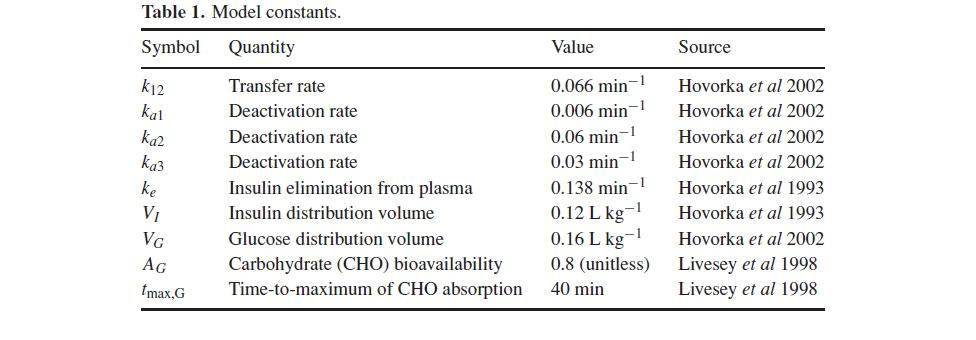

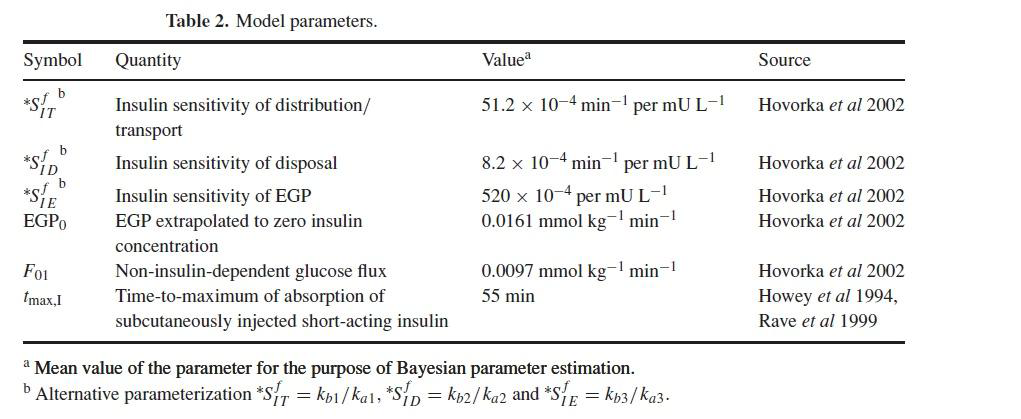

function main() 
    params = initialize_parameters();
    y0 = initialize_state(params); 
    [tspan, meal_times, meal_amounts, basal_rate, bolus_amounts] = simulation_setup(); 
    [t, y] = solve_system(tspan, y0, meal_times, meal_amounts, basal_rate, params, bolus_amounts); 
    results = process_results(t, y, meal_times, meal_amounts, params); 
    plot_results(results, meal_times); 
end

Esta sección define los parámetros fisiológicos y farmacocinéticos del modelo glucosa-insulina. Incluye constantes para la absorción de insulina y glucosa, volúmenes de distribución y tasas de acción insulínica. Estos valores están basados en literatura clínica para pacientes con diabetes tipo 1.

function params = initialize_parameters()
    %(Tabla 1)
    params.k12 = 0.066;       % min^-1
    params.ka1 = 0.006;      % min^-1
    params.ka2 = 0.06;       % min^-1
    params.ka3 = 0.03;      % min^-1
    params.ke = 0.138;      % min^-1
    params.VI = 0.12;        % L/kg
    params.VG = 0.16;        % L/kg
    params.AG = 0.8;         % adimensional
    params.t_maxG = 40;      % min
    % (Tabla 2)
    params.kb1 = 51.2e-4;   % min^-1 per mU/L
    params.kb2 = 8.2e-4;    % min^-1 per mU/L
    params.kb3 = 520e-4;    % adimensional per mU/L
    params.EGP0 = 0.0161;   % mmol/kg/min
    params.F01 = 0.0097;     % mmol/kg/min
    params.t_maxI = 55;     % min
end

Se establece el estado inicial del sistema, incluyendo la concentración basal de glucosa y un nivel nulo de insulina plasmática, en concordancia con un paciente con diabetes tipo 1 que no produce insulina endógena. Los estados se representan como masas (en mmol/kg) y unidades de insulina (U).

function y0 = initialize_state(params)
    G0_mmol_L = 6;          % Concentracion inicial de glucosa en mmol/L
    I0 = 0;                 % mU/L 
    y0 = [params.VG * G0_mmol_L; % Q1 (mmol/kg)
          0;                   % Q2 (mmol/kg) - CAMBIO: Se puso en 0 para una inicialización estándar
          0;                   % S1 (U)
          0;                   % S2 (U)
          I0;                  % I (mU/L)
          0;                   % x1
          0;                   % x2
          0];                  % x3
end

Esta sección define los tiempos y cantidades de comidas, la tasa basal de insulina (puede ser cero en T1D sin bomba) y los bolos de insulina preprandiales. La simulación cubre un periodo de 24 horas (1440 minutos).

function [tspan, meal_times, meal_amounts, basal_rate, bolus_amounts] = simulation_setup()
    tspan = [0 1440]; % Tiempo de simulación (1440 minutos = 24 horas)
    meal_times = [480, 720, 1200]; % Hora de las comidas
    meal_amounts = [30, 60, 50]; % Cantidad de carbohidratos para cada comida (g)
    basal_rate = 0.000001;  % Tasa basal de insulina (U/min)
    bolus_amounts = [4, 4, 5]; % Bolos de insulina para cada comida
end

Se utiliza el solver `ode45` para resolver el modelo de manera segmentada, aplicando bolos de insulina en los tiempos definidos. La integración se detiene en cada evento de bolo, permitiendo una actualización puntual del sistema.

function [t, y] = solve_system(tspan, y0, meal_times, meal_amounts, basal_rate, params, bolus_amounts)
    options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9); 
    bolus_times = meal_times - 30; % Calculamos los tiempos de bolo, 30 minutos antes de cada comida
    % Definir una función de evento para la administración de bolos
    % Los eventos ahora se disparan en bolus_times
    bolus_event_fcn = @(t, y) bolus_events(t, y, bolus_times);
    options = odeset(options, 'Events', bolus_event_fcn);

    t_start = tspan(1);
    y_current = y0;
    t_out = [];
    y_out = [];
    
    % Iterar a través de los tiempos de bolo, y luego el segmento final
    for i = 1:length(bolus_times) + 1
        % Determinar el tiempo final para este segmento
        if i <= length(bolus_times)
            t_end_segment = bolus_times(i); % El segmento termina en el tiempo del bolo
        else
            t_end_segment = tspan(2); % Último segmento hasta el final de la simulación
        end
        
        % Asegurarse de que t_start no sea mayor que t_end_segment
        if t_start >= t_end_segment && i <= length(bolus_times)
            % Si ya pasamos el tiempo del bolo o estamos en el mismo instante,
            % aplicar el bolo inmediatamente y avanzar.
            % Esto maneja el caso si t_start es exactamente el tiempo del bolo o si un bolo es al tiempo 0.
            if t_start == bolus_times(i)
                y_current(3) = y_current(3) + bolus_amounts(i); 
                t_start = bolus_times(i); % Asegurarse de que el tiempo de inicio es el correcto para el siguiente segmento
                continue; % Saltar a la siguiente iteración del bucle
            end
        elseif t_start >= tspan(2) % Si ya estamos al final de la simulación
            break;
        end


        % Resolver EDO para el segmento actual
        [t_segment, y_segment] = ode45(@(t,y) model_equations(t, y, meal_times, meal_amounts, basal_rate, params), ...
                                       [t_start, t_end_segment], y_current, options);
        
        % Añadir resultados, excluyendo puntos de tiempo duplicados
        if ~isempty(t_out) && t_segment(1) == t_out(end)
            t_out = [t_out; t_segment(2:end)];
            y_out = [y_out; y_segment(2:end,:)];
        else
            t_out = [t_out; t_segment];
            y_out = [y_out; y_segment];
        end
        
        % Si se alcanzó un evento (tiempo de bolo), aplicar el bolo
        if i <= length(bolus_times) && t_segment(end) >= bolus_times(i) - 1e-6 % Verificar si se alcanzó el tiempo del bolo
            y_current = y_segment(end,:);
            % Aplicar bolo a S1 (y(3))
            y_current(3) = y_current(3) + bolus_amounts(i); 
        else
            y_current = y_segment(end,:);
        end
        
        t_start = t_end_segment;
        if t_start >= tspan(2) % Si hemos alcanzado el tiempo final general, salir
            break;
        end
    end
    t = t_out;
    y = y_out;
end

function [value,isterminal,direction] = bolus_events(t, y, bolus_times) % Ahora usa bolus_times
    value = zeros(size(bolus_times));
    for i = 1:length(bolus_times)
        value(i) = t - bolus_times(i); % Evento cuando t sea igual a bolus_times(i)
    end
    isterminal = ones(size(bolus_times)); % Detener la integración en el evento
    direction = ones(size(bolus_times)); % Detectar evento cuando el valor es creciente (t pasa bolus_time)
end

Aquí se implementa el conjunto de ecuaciones diferenciales del modelo. Incluye la dinámica de glucosa, la absorción y acción de la insulina, y la aparición de glucosa intestinal tras las comidas. Cada subcomponente se implementa en funciones separadas para mejorar la modularidad.

function dy = model_equations(t, y, meal_times, meal_amounts, basal_rate, params)
    Q = y(1:2); 
    S = y(3:4);
    I = y(5);
    x = y(6:8);
    U_G = calculate_glucose_absorption(t, meal_times, meal_amounts, params); % Calcular absorción de glucosa intestinal
    [dS, U_I] = insulin_absorption_dynamics(S, basal_rate, params);  % Dinámica de absorción de insulina
    dI = plasma_insulin_dynamics(I, U_I, params);  % Dinámica de insulina plasmática
    dx = insulin_action_dynamics(x, I, params); % Acción de la insulina
    dQ = glucose_dynamics(Q, x, U_G, params); % Dinámica de glucosa
    dy = [dQ; dS; dI; dx];  % Combinar todas las derivadas
end

Se modela la tasa de absorción intestinal utilizando una función basada en el tiempo desde la ingestión, con una forma suavizada que aproxima la cinética de digestión y absorción de carbohidratos.

function U_G = calculate_glucose_absorption(t, meal_times, meal_amounts, params)
    U_G = 0; 
    for i = 1:length(meal_times)
        if t >= meal_times(i)
            time_since_meal = t - meal_times(i); 
            U_G = U_G + (meal_amounts(i) * params.AG * time_since_meal * ...
                  exp(-time_since_meal/params.t_maxG)) / (params.t_maxG^2); 
        end
    end
end

function [dS, U_I] = insulin_absorption_dynamics(S, basal_rate, params)
    dS1 = basal_rate - S(1)/params.t_maxI; 
    dS2 = S(1)/params.t_maxI - S(2)/params.t_maxI;
    U_I = S(2)/params.t_maxI; % Tasa de aparición de insulina en plasma
    dS = [dS1; 
          dS2];
end

function dI = plasma_insulin_dynamics(I, U_I, params)
    dI = U_I/params.VI - params.ke*I; 
end

function dx = insulin_action_dynamics(x, I, params)
    dx1 = -params.ka1*x(1) + params.kb1*I;
    dx2 = -params.ka2*x(2) + params.kb2*I; 
    dx3 = -params.ka3*x(3) + params.kb3*I;
    dx = [dx1; dx2; dx3]; 
end

function dQ = glucose_dynamics(Q, x, U_G, params)
    G_mmol_L = Q(1) / params.VG;  % Concentración de glucosa medida en mmol/L  

    if G_mmol_L >= 4.5
        F01c = params.F01; 
    else
        F01c = params.F01 * G_mmol_L / 4.5; % Flujo no dependiente de insulina corregido (still uses mmol/L for threshold)
    end
    
    if G_mmol_L >= 9
        FR = 0.003 * (G_mmol_L - 9) * params.VG; % Clearance renal de glucosa (still uses mmol/L for threshold)
    else
        FR = 0; 
    end
     
    dQ1 = -(F01c/(params.VG*G_mmol_L) + x(1))*Q(1) + params.k12*Q(2) - FR + U_G + params.EGP0*(1 - x(3)); 
    dQ2 = x(1)*Q(1) - (params.k12 + x(2))*Q(2);% Ecuaciones diferenciales
    dQ = [dQ1; dQ2]; 
end

function results = process_results(t, y, meal_times, meal_amounts, params)
    results.t = t;
    results.y = y;
    
    results.G = (y(:,1) / params.VG) * 18.0156; %Convierte glucosa de mmol/L a mg/dL for
    results.I = y(:,5) * 0.1; % Convierte insulina de mU/L a mU/dL 
    
    results.x1 = y(:,6); % Acción de insulina en transporte
    results.x2 = y(:,7); % Acción de insulina en disposición
    results.x3 = y(:,8); % Acción de insulina en producción endógena
    
    results.U_I = y(:,4)/params.t_maxI; % Calcular tasa de absorción de insulina
    results.U_G = zeros(size(t));  % Calcular absorción de glucosa intestinal
    for i = 1:length(meal_times)
        for j = 1:length(t)
            if t(j) >= meal_times(i)
                time_since_meal = t(j) - meal_times(i); 
                results.U_G(j) = results.U_G(j) + ...
                    (meal_amounts(i) * params.AG * time_since_meal * ...
                    exp(-time_since_meal/params.t_maxG)) / (params.t_maxG^2); 
            end
        end
    end
end

Se grafican seis variables clave del modelo: glucosa e insulina plasmática, acciones de la insulina, absorción intestinal de glucosa, aparición de insulina en plasma y masas de glucosa en los compartimentos accesible y no accesible. El subplot de glucosa incluye líneas de referencia para los límites seguros (70–180 mg/dL) y sombreado para zonas de riesgo.

function plot_results(results, meal_times)
    figure('Position', [100, 100, 1200, 800]); 
    
    t_hours = results.t / 60;% Convertir tiempo de minutos a horas
    meal_times_hours = meal_times / 60;
    bolus_times_hours = (meal_times - 30) / 60;

    subplot(2, 1, 1);
    hold on;
    
    yline(70, '--r', 'LineWidth', 1.5, 'Alpha', 0.7);
    yline(180, '--r', 'LineWidth', 1.5, 'Alpha', 0.7);

    text(0.5, 75, '← Hipoglucemia', 'Color', 'blue', 'FontWeight','bold');
    text(0.5, 185, 'Hiperglucemia →', 'Color', 'red', 'FontWeight','bold', 'HorizontalAlignment','left');
    
    y_limits = [0, max(results.G)*1.1];
    area(t_hours, results.G < 70 .* results.G, 'FaceColor', [1 0.8 0.8], 'EdgeColor', 'none', 'HandleVisibility', 'off');% Sombras de hipo e hiperglucemia
    area(t_hours, results.G > 180 .* results.G, 'FaceColor', [1 1 0.6], 'EdgeColor', 'none', 'HandleVisibility', 'off');
    
    h_glucosa = plot(t_hours, results.G, 'b', 'LineWidth', 2, 'DisplayName', 'Glucosa plasmática');% Curva de glucosa
    h_comida = line([meal_times_hours(1) meal_times_hours(1)], y_limits,'Color', 'g', 'LineStyle', '--', 'DisplayName', 'Comidas');

    for i = 2:length(meal_times_hours)
        line([meal_times_hours(i) meal_times_hours(i)], y_limits,'Color', 'g', 'LineStyle', '--', 'HandleVisibility', 'off');
    end
    
    xlim([0 24])
    ylim(y_limits);
    title('Respuesta glucemica 24 horas con 3 comidas');
    xlabel('Tiempo (horas)'); 
    ylabel('Glucosa (mg/dL)'); 
    legend([h_glucosa, h_comida], 'Location', 'northeast');
    grid on;
     
    subplot(2, 1, 2);
    hold on;
    
    h_insulina = plot(t_hours, results.I, 'r', 'LineWidth', 2, 'DisplayName', 'Insulina plasmática');  
    h_bolo = line([bolus_times_hours(1) bolus_times_hours(1)], get(gca, 'YLim'),'Color', 'k', 'LineStyle', '-.', 'LineWidth', 1.5, 'DisplayName', 'Aplicación');
    
    for i = 2:length(bolus_times_hours)
        line([bolus_times_hours(i) bolus_times_hours(i)], get(gca, 'YLim'),'Color', 'k', 'LineStyle', '-.', 'LineWidth', 1.5, 'HandleVisibility', 'off');
    end
    
    xlim([0 24]);
    ylim([0, max(results.I)*1.1]);
    title('Niveles de insulina');
    xlabel('Tiempo (horas)'); 
    ylabel('Insulina (mU/dL)'); 
    legend([h_insulina, h_bolo], 'Location', 'northeast');
    grid on;
end

Finalmente, se llama a la función `main`, que organiza toda la simulación paso a paso: inicialización, resolución del sistema y graficación de resultados.

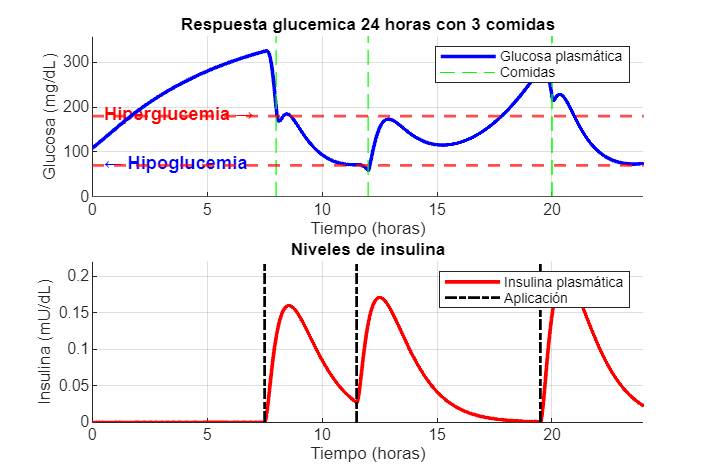

main;

La evolución de la glucosa plasmática a lo largo de las 24 horas muestra una clara respuesta postprandial tras cada una de las tres comidas simuladas. Especialmente después del desayuno y la cena, se observa un incremento pronunciado de la glucosa por encima de los 180 mg/dL, superando en el primer caso los 300 mg/dL, lo cual indica un episodio de hiperglucemia. Esto sugiere que los bolos de insulina aplicados no fueron suficientes o no se administraron con la anticipación óptima. La respuesta tras el almuerzo, aunque también presenta un aumento, es más controlada, posiblemente debido a una mayor acción acumulada de la insulina.

La insulina plasmática muestra picos bien definidos después de cada bolo subcutáneo administrado 30 minutos antes de las comidas. El comportamiento decreciente posterior a cada bolo refleja la farmacocinética típica de la insulina rápida. Dado que la tasa basal de insulina es prácticamente nula, la insulina desaparece del sistema entre comidas, lo que permite que la glucosa vuelva a subir con mayor facilidad. Este patrón es característico en pacientes con diabetes tipo 1 que dependen exclusivamente de insulina exógena para el control glucémico.

En cuanto a las acciones de la insulina (x₁, x₂, x₃), se evidencia que la supresión de la producción endógena de glucosa (x₃) es la acción más intensa, alcanzando valores mayores que el transporte (x₁) y la disposición periférica (x₂). Esta dominancia de la acción hepática contribuye a reducir parcialmente la glucosa plasmática después de las comidas. Las curvas muestran una dinámica retardada respecto a la concentración de insulina, lo cual es coherente con los mecanismos fisiológicos de acción secundaria de la insulina sobre los tejidos.

La tasa de absorción intestinal de glucosa presenta tres picos, cada uno correspondiente a una comida. El mayor de estos ocurre tras el almuerzo, reflejando el mayor consumo de carbohidratos. Las formas suaves de las curvas son producto del uso de una función de absorción continua y diferenciable, que representa adecuadamente la cinética gastrointestinal. Estos flujos entran directamente al compartimento de glucosa accesible, elevando transitoriamente la glucosa plasmática.

La tasa de aparición de insulina  describe el paso desde el tejido subcutáneo al plasma. Se observa un desfase entre los tiempos de bolo y el pico efectivo de, lo cual es consistente con la absorción retardada de la insulina inyectada. Esto refuerza la importancia de aplicar los bolos con suficiente anticipación para prevenir hiperglucemias postprandiales.

Finalmente, la evolución de las masas de glucosa en los compartimentos accesible (Q₁) y no accesible (Q₂) revela el intercambio dinámico entre estos. Tras las comidas, Q₂ actúa como un amortiguador al absorber parte de la glucosa disponible, para luego cederla lentamente a Q₁. Esta interacción genera un efecto prolongado sobre la glucosa plasmática, incluso después de que la absorción intestinal ha cesado.